%% ex3_gene_expression_saddlenode.m
% Gene expression model:
%   x' = -a x + y
%   y' =  x^2/(1+x^2) - b y
%
% Nullclines:
%   x'=0 => y = a x
%   y'=0 => y = (1/b) * x^2/(1+x^2)
%
% Equilibria satisfy: y = a x and y = (1/b)*x^2/(1+x^2)
% => a x = (1/b)*x^2/(1+x^2)
% => x=0 always, and for x>0:
%    a b = x/(1+x^2)
%
% Let k = a b. The function f(x)=x/(1+x^2) attains max 1/2 at x=1.
% Thus saddle-node threshold: k_c = 1/2  <=>  a b = 1/2.

clear; close all; clc;

a = 1;                    % fix a
b_c = 1/(2*a);            % saddle-node threshold in b

fprintf('Saddle-node threshold: b_c = %.4f (since a=%.3g)\n', b_c, a);

Saddle-node threshold: b_c = 0.5000 (since a=1)


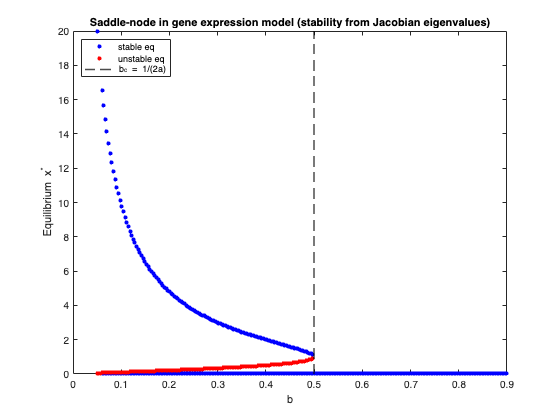


%% Bifurcation diagram for equilibria vs b
b_vals = linspace(0.05, 0.9, 250);
x_eq_list = []; b_plot = []; stab_plot = [];

for b = b_vals
    k = a*b;

    % equilibrium x=0 branch
    [stable0] = is_stable_equilibrium(a,b,0,a*0);
    x_eq_list(end+1) = 0; %#ok<SAGROW>
    b_plot(end+1) = b;   %#ok<SAGROW>
    stab_plot(end+1) = stable0; %#ok<SAGROW>

    % positive equilibria exist if k <= 1/2
    if k <= 0.5
        disc = 1 - 4*k^2;
        disc = max(disc,0);
        x1 = (1 - sqrt(disc))/(2*k);
        x2 = (1 + sqrt(disc))/(2*k);

        % y = a x
        y1 = a*x1; y2 = a*x2;

        s1 = is_stable_equilibrium(a,b,x1,y1);
        s2 = is_stable_equilibrium(a,b,x2,y2);

        x_eq_list = [x_eq_list, x1, x2]; %#ok<AGROW>
        b_plot     = [b_plot, b,  b];   %#ok<AGROW>
        stab_plot  = [stab_plot, s1, s2]; %#ok<AGROW>
    end
end

figure('Name','Gene expression: saddle-node bifurcation'); hold on; box on;

% stable: solid; unstable: dashed
stableMask = (stab_plot==1);
unstMask   = (stab_plot==0);

plot(b_plot(stableMask), x_eq_list(stableMask), 'b.', 'MarkerSize', 12);
plot(b_plot(unstMask),   x_eq_list(unstMask),   'r.', 'MarkerSize', 12);

xline(b_c, 'k--', 'LineWidth', 1.5);
xlabel('b'); ylabel('Equilibrium x^*');
title('Saddle-node in gene expression model (stability from Jacobian eigenvalues)');
legend({'stable eq','unstable eq','b_c = 1/(2a)'}, 'Location','northwest');

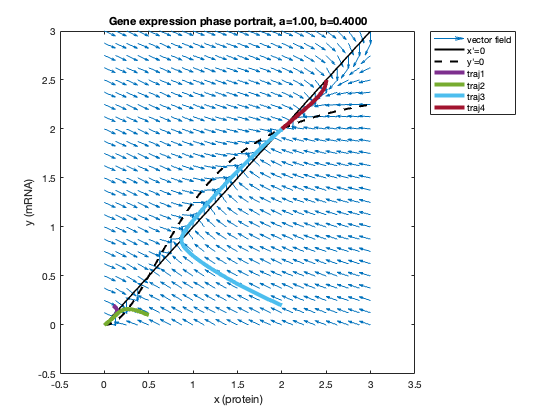

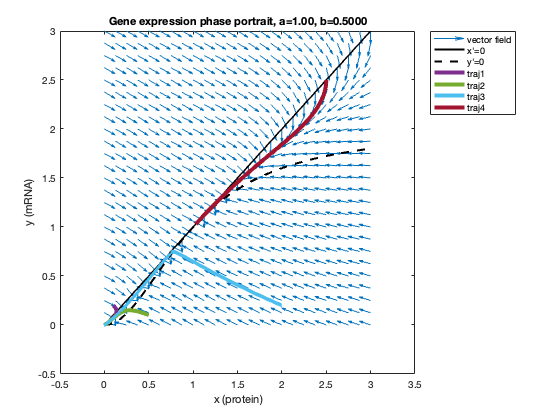

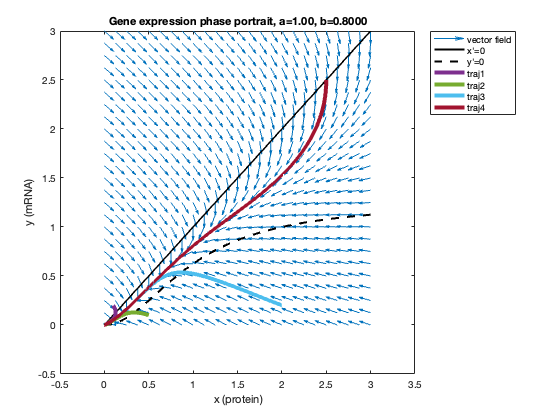


%% Phase portraits for b below/near/above the saddle-node
b_show_list = [0.40, b_c, 0.80];

for jj = 1:numel(b_show_list)
    b = b_show_list(jj);

    figure('Name',sprintf('Phase portrait (b=%.3f)',b)); hold on; box on;

    % Vector field on a reasonable domain
    xg = linspace(0, 3, 25);
    yg = linspace(0, 3, 25);
    [X,Y] = meshgrid(xg,yg);
    dX = -a*X + Y;
    dY = (X.^2)./(1+X.^2) - b*Y;
    [U,V] = normalize_quiver(dX,dY);
    quiver(X,Y,U,V,0.8);

    % Nullclines
    xx = linspace(0,3,1200);
    y_xnull = a*xx;
    y_ynull = (1/b) * (xx.^2)./(1+xx.^2);
    plot(xx, y_xnull, 'k-',  'LineWidth', 2);
    plot(xx, y_ynull, 'k--', 'LineWidth', 2);

    % Simulate a few trajectories
    opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.5);
    tspan = [0 200];
    ICs = [0.1 0.2;  0.5 0.1;  2.0 0.2;  2.5 2.5]';

    for k = 1:size(ICs,2)
        z0 = ICs(:,k);
        [t,z] = ode45(@(t,z) gene_ode(t,z,a,b), tspan, z0, opts);
        plot(z(:,1), z(:,2), 'LineWidth',4);
    end

    xlabel('x (protein)'); ylabel('y (mRNA)');
    title(sprintf('Gene expression phase portrait, a=%.2f, b=%.4f', a, b));
    legend({'vector field','x''=0','y''=0','traj1','traj2','traj3','traj4'}, ...
        'Location','northeastoutside');
end


%% ---- Local functions ----

function dz = gene_ode(~, z, a, b)
    x = z(1); y = z(2);
    dx = -a*x + y;
    dy = x^2/(1+x^2) - b*y;
    dz = [dx; dy];
end

function stable = is_stable_equilibrium(a,b,x,y)
    % Jacobian:
    % J = [ -a, 1;
    %       d/dx(x^2/(1+x^2)),  -b ]
    dfdx = 2*x/(1+x^2)^2;
    J = [-a, 1; dfdx, -b];
    ev = eig(J);
    stable = all(real(ev) < 0);
end

function [U,V] = normalize_quiver(Uraw, Vraw)
    S = sqrt(Uraw.^2 + Vraw.^2);
    S(S==0) = 1;
    U = Uraw ./ S;
    V = Vraw ./ S;
end
